%Engineering Computer Applications Final Project
%Benjamin Oakes & Dakota D'Angelo


clear;
clc;
close all;

t_hours = (0:30/3600:5)'; 

altitude_ft = zeros(size(t_hours));
speed_kts = zeros(size(t_hours));

t_takeoff_end = 0.1;  
t_climb_end = 1.0;    
t_cruise_end = 4.0;   
t_descent_end = 5.0;  

idx_takeoff = t_hours <= t_takeoff_end;
altitude_ft(idx_takeoff) = 10000 * (t_hours(idx_takeoff) / t_takeoff_end).^2;
speed_kts(idx_takeoff) = 250 * (t_hours(idx_takeoff) / t_takeoff_end);

idx_climb = (t_hours > t_takeoff_end) & (t_hours <= t_climb_end);
t_climb_segment = t_hours(idx_climb) - t_takeoff_end;
climb_duration = t_climb_end - t_takeoff_end;
altitude_ft(idx_climb) = altitude_ft(find(idx_takeoff,1,'last')) + ...
    (35000 - altitude_ft(find(idx_takeoff,1,'last'))) * (t_climb_segment / climb_duration);
speed_kts(idx_climb) = 250 + (450 - 250) * (t_climb_segment / climb_duration);

idx_cruise = (t_hours > t_climb_end) & (t_hours <= t_cruise_end);
altitude_ft(idx_cruise) = 35000 + 500 * sin(2 * pi * (t_hours(idx_cruise) - t_climb_end)); 
speed_kts(idx_cruise) = 450 + 10 * cos(4 * pi * (t_hours(idx_cruise) - t_climb_end)); 

idx_descent = (t_hours > t_cruise_end) & (t_hours <= t_descent_end);
t_descent_segment = t_hours(idx_descent) - t_cruise_end;
descent_duration = t_descent_end - t_cruise_end;
altitude_ft(idx_descent) = 35000 * (1 - (t_descent_segment / descent_duration).^1.5);
speed_kts(idx_descent) = 450 - (450 - 50) * (t_descent_segment / descent_duration);

flightDataTable = table(t_hours, altitude_ft, speed_kts, 'VariableNames', {'Time_hr', 'Altitude_ft', 'Speed_kts'});
writetable(flightDataTable, 'flight_data.csv');

data = readtable('flight_data.csv');
time = data.Time_hr;
altitude = data.Altitude_ft;
speed = data.Speed_kts;

CRUISE_ALT_THRESHOLD = 30000; 
alt_rate = [0; diff(altitude) ./ diff(time)]; % ft/hr
phases = strings(length(time), 1);

for i = 1:length(time)
    if altitude(i) > CRUISE_ALT_THRESHOLD
        phases(i) = "Cruise";
    elseif alt_rate(i) > 500
        if speed(i) < 200
            phases(i) = "Takeoff";
        else
            phases(i) = "Climb";
        end
    elseif alt_rate(i) < -500
        phases(i) = "Descent";
    else
        if altitude(i) < 1000
            phases(i) = "Takeoff";
        else
            phases(i) = "Cruise";
        end
    end
end
phases = categorical(phases);

max_climb_rate = max(alt_rate(phases == "Climb")) / 60;


avg_cruise_speed = mean(speed(phases == "Cruise"));


descent_duration_min = sum(phases == "Descent") * (time(2) - time(1)) * 60;

fprintf('Max Climb Rate: %.2f ft/min\n', max_climb_rate);

Max Climb Rate: 3194.44 ft/min


fprintf('Avg Cruise Speed: %.2f kts\n', avg_cruise_speed);

Avg Cruise Speed: 444.72 kts


fprintf('Descent Duration: %.2f min\n', descent_duration_min);

Descent Duration: 44.00 min


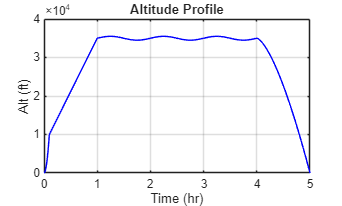


figure; plot(time, altitude, 'b'); title('Altitude Profile'); xlabel('Time (hr)'); ylabel('Alt (ft)'); grid on;

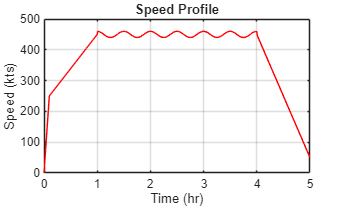

figure; plot(time, speed, 'r'); title('Speed Profile'); xlabel('Time (hr)'); ylabel('Speed (kts)'); grid on;

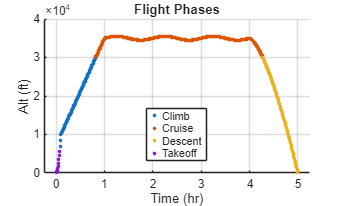

figure; gscatter(time, altitude, phases); title('Flight Phases'); xlabel('Time (hr)'); ylabel('Alt (ft)'); grid on;

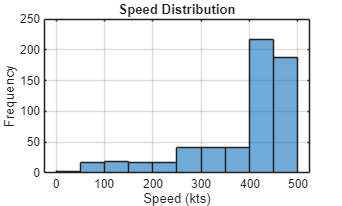

figure; histogram(speed); title('Speed Distribution'); xlabel('Speed (kts)'); ylabel('Frequency'); grid on;

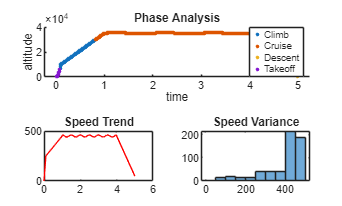

figure('Name', 'Dashboard');
tiledlayout(2,2);
nexttile([1 2]); gscatter(time, altitude, phases); title('Phase Analysis');
nexttile; plot(time, speed, 'r'); title('Speed Trend');
nexttile; histogram(speed); title('Speed Variance');